# Podstawy stereowizji

## Kalibracja

W celu wyznaczenia położenia wybranych punktów w przestrzeni na podstawie pary obrazów, konieczna jest znajomość parametrów zestawu stereo (schematycznie przedstawionego poniżej). Oprócz parametrów wewnętrznych każdej z kamer (takich jak *f* i *c*) konieczna jest znajomość wzajemnego położenia i orientacji kamer.

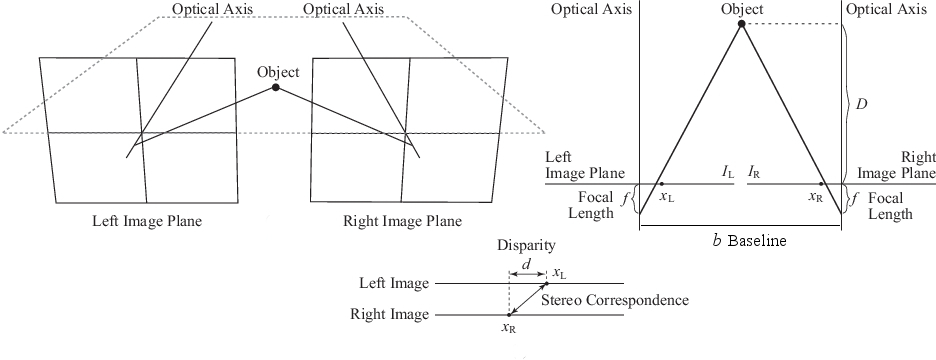

Zwykle dąży się do stanu, w którym kamery mają równoległe osie optyczne, a ich odległość jest znana i zadana z góry. W rzeczywistości jednak nie da się tego zrobić bezbłędnie, w związku z czym parametry te podlegają procesowi kalibracji (podobnie jak macierz kamery). W tym celu wykorzystać można Stereo Camera Calibrator App (można też zaimplementować podobny proces ręcznie korzystając z funkcji [estimateCameraParameters](https://www.mathworks.com/help/vision/ref/estimatecameraparameters.html)).

Proces kalibracji przebiega podobnie jak przy pojedynczej kamerze. Po podaniu zestawów obrazów dla lewej i prawej kamery wyznaczone zostaną wszystkie istotne parametry.

Pierwszym krokiem jest detekcja szachownicy w obrazach z obu kamer:

% leftImages = imageDatastore(fullfile(toolboxdir('vision'),'visiondata', 'calibration','stereo','left'));
% rightImages = imageDatastore(fullfile(toolboxdir('vision'),'visiondata', 'calibration','stereo','right'));
% squareSize = 108;

leftImages = imageDatastore("left");
rightImages = imageDatastore("right");
squareSize = 40;

[imagePoints, boardSize, pairsUsed] = detectCheckerboardPoints(leftImages.Files,rightImages.Files);

Ustalenie parametrów szachownicy kalibracyjnej:

worldPoints = generateCheckerboardPoints(boardSize,squareSize);

Kalibracja zestawu kamer:

I = readimage(leftImages,1); 
imageSize = [size(I,1),size(I,2)];
stereoParams = estimateCameraParameters(imagePoints,worldPoints, 'ImageSize',imageSize);

Dokładność kaliubracji można ocenić na podstawie analizy błędów reprojekcji:

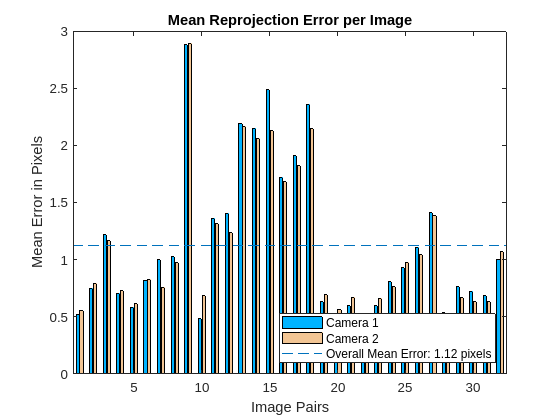

showReprojectionErrors(stereoParams);

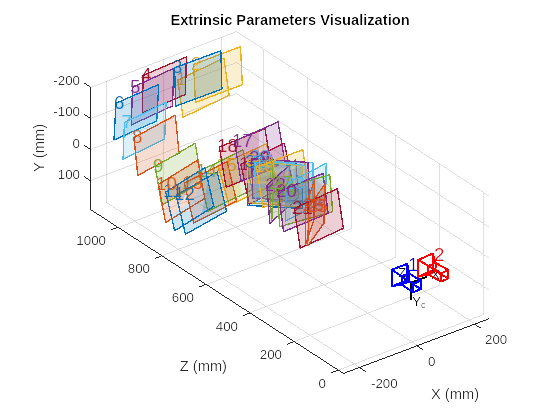

figure;
showExtrinsics(stereoParams);

## Wyznaczenie odległości do zadanych punktów

Znając parametry zestawu stereo można wyprostować odpowiadające sobie obrazy tak, żeby linie epipolarne były poziome i miały tę samą współrzędną *y:*

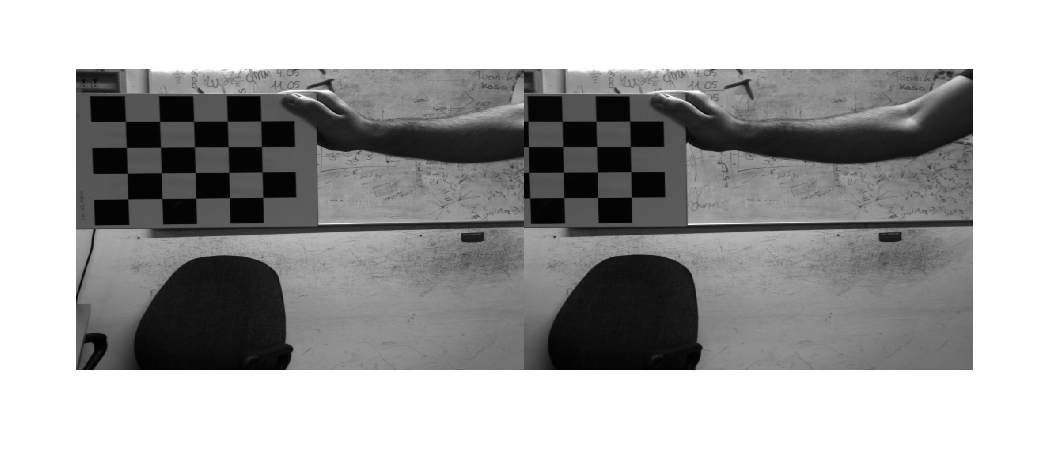

sel_id = 20;
I1 = imread(leftImages.Files{sel_id});
I2 = imread(rightImages.Files{sel_id});

% rectify images using calculated stereo parameters
[J1, J2] = rectifyStereoImages(I1, I2, stereoParams);

imshowpair(J1, J2, 'montage');

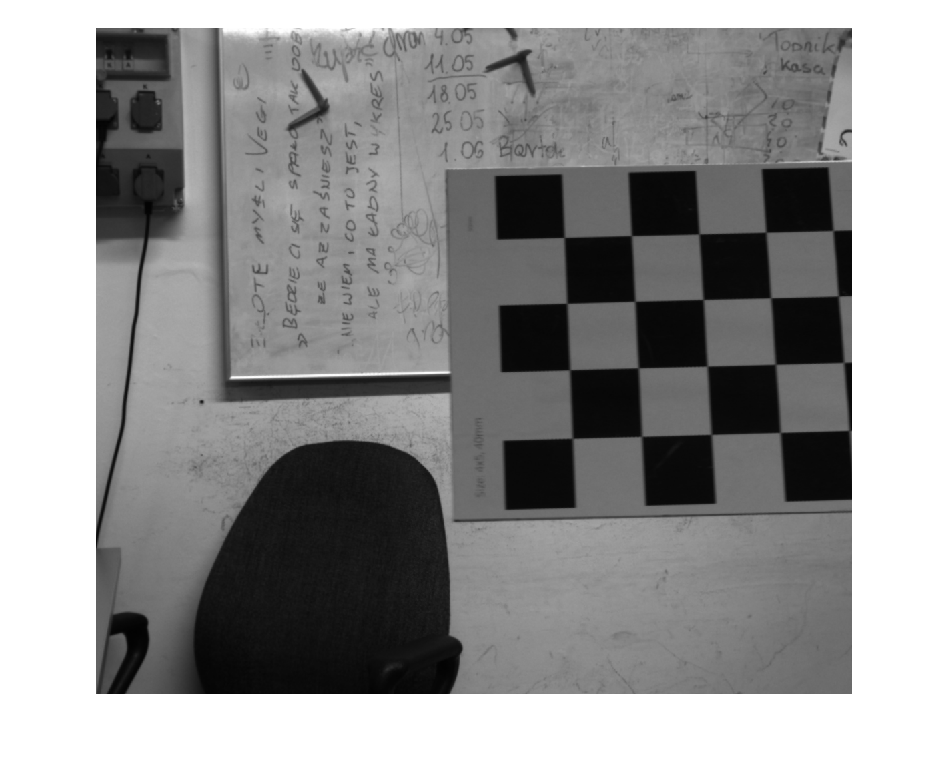

figure;
imshow(J1);
[x1, y1] = getpts;

imshow(J2);
[x2, y2] = getpts;

%worldPoints = triangulate([x1, y1], [x2, y2], stereoParams)
[x1, y1]

ans =   218.2129  347.0888


[x2, y2]

ans =    14.5095  344.1579


z = stereoParams.CameraParameters1.FocalLength(1) * abs(stereoParams.TranslationOfCamera2(1)) / abs(x1-x2)

z = 1.0094e+03

## Dopasowanie punktów kluczowych i wyznaczenie rzadkiej chmury punktów

Mając metodę określania odległości do par punktów można ją wykorzystać do stworzenia rzadkiej chmury punktów. Po wykryciu i dopasowaniu punktów kluczowych w obu obrazach można wyznaczyć ich położenie w przestrzeni.

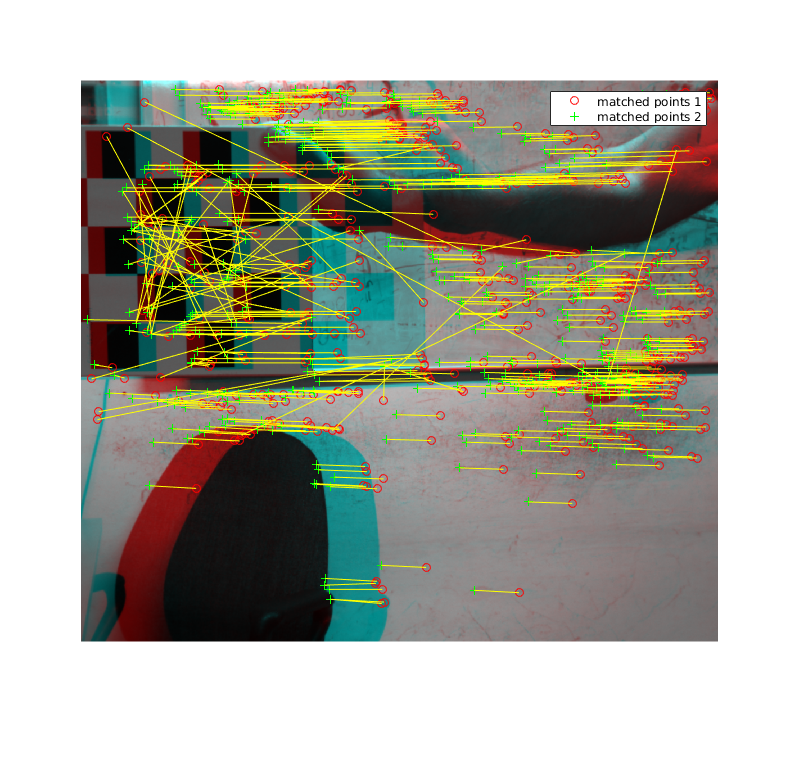

points1 = detectSURFFeatures(J1, 'MetricThreshold', 200);
points2 = detectSURFFeatures(J2, 'MetricThreshold', 200);

[f1,vpts1] = extractFeatures(J1, points1);
[f2,vpts2] = extractFeatures(J2, points2);

indexPairs = matchFeatures(f1,f2) ;
matchedPoints1 = vpts1(indexPairs(:,1));
matchedPoints2 = vpts2(indexPairs(:,2));

figure; showMatchedFeatures(J1,J2,matchedPoints1,matchedPoints2);
legend('matched points 1','matched points 2');

Wśród dopasowanych par punktów znajdują się dopasowania nieprawidłowe. Zgodnie z założeniami, punkty odpowiadające sobie powinny leżeć na tej samej współrzędnej *y, *można więc wyrzucić wszystkie pary, które tego warunku nie spełniają:

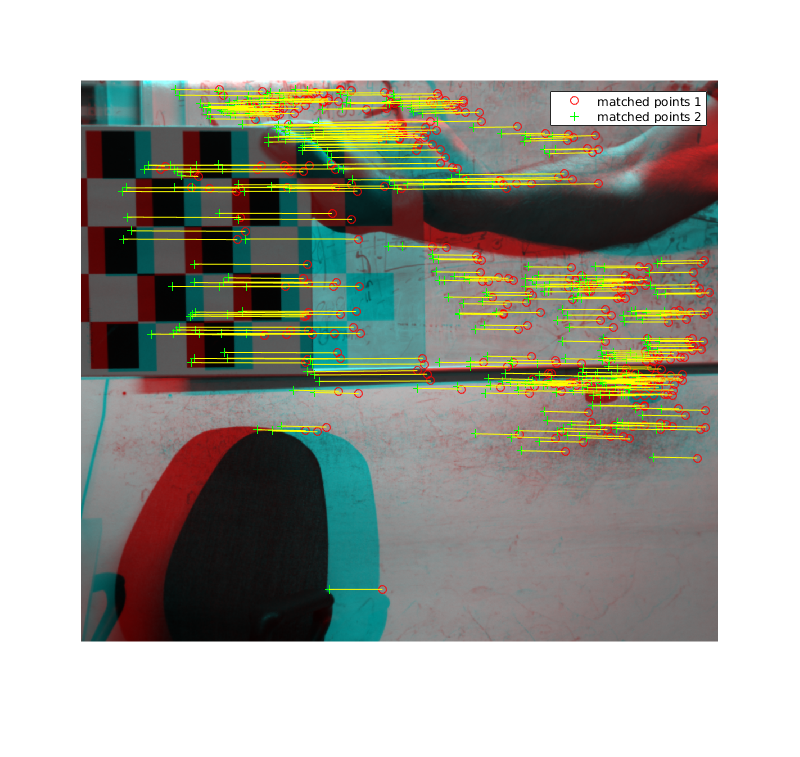

y_diff = abs(matchedPoints1.Location(:,2) - matchedPoints2.Location(:,2));
y_mask = y_diff < 2;
filteredPoints1 = matchedPoints1(y_mask);
filteredPoints2 = matchedPoints2(y_mask);

figure; showMatchedFeatures(J1,J2,filteredPoints1,filteredPoints2);
legend('matched points 1','matched points 2');

Po wyznaczeniu odpowiednich par można obliczyć ich położenie w przestrzeni oraz wyświetlić chmurę punktów.

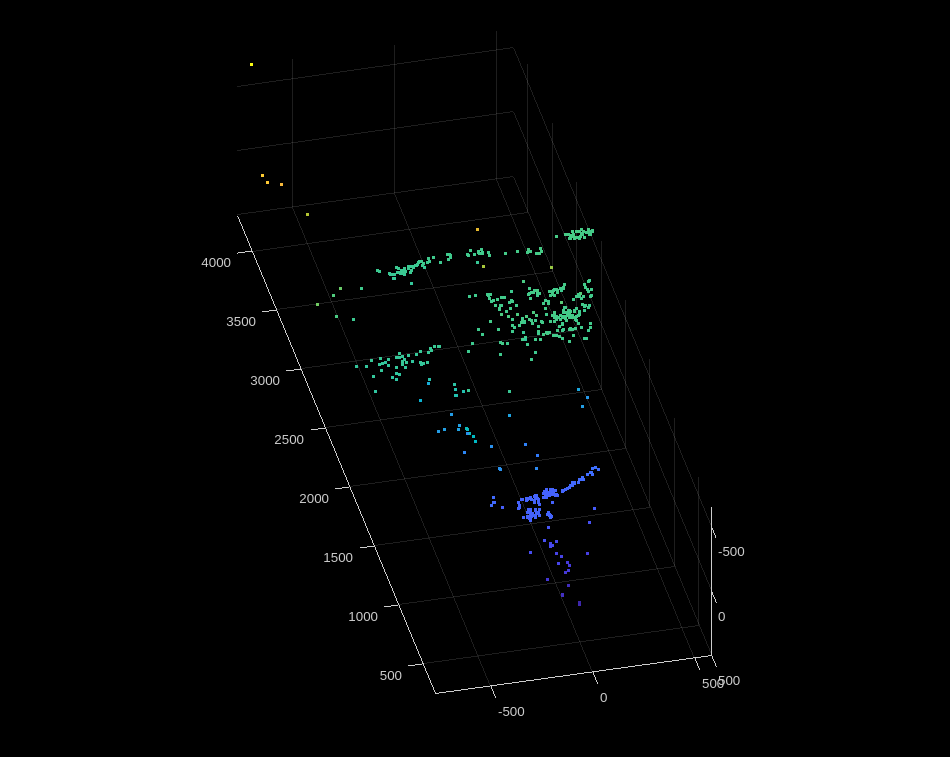

d = abs(matchedPoints1.Location(:,1) - matchedPoints2.Location(:,1));
fx = stereoParams.CameraParameters1.FocalLength(1);
fy = stereoParams.CameraParameters1.FocalLength(2);
cx = stereoParams.CameraParameters1.PrincipalPoint(1);
cy = stereoParams.CameraParameters1.PrincipalPoint(2);
z = fx * abs(stereoParams.TranslationOfCamera2(1)) ./ d;
u = matchedPoints1.Location(:, 1);
v = matchedPoints1.Location(:, 2);
x = z .* (u-cx) / fx;
y = z .* (v-cy) / fy;

limit = 5000;
x = x(z < limit);
y = y(z < limit);
z = z(z < limit);


ptCloud = pointCloud([x, y, z]);
pcshow(ptCloud, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', 'MarkerSize', 45);

## Wyznaczenie gęstej mapy głębi

Oprócz rzadkiej chmury punktów (bazującej na dopasowaniach punktów kluczowych) możliwe jest też wyznaczenie gęstej mapy głębi dla pary obrazów stereo. Algorytmy typu *stereo disparity* w pierwszym kroku wyznaczają obraz różnic w położeniu (poziomym) punktów w obrazach, a na tej podstawie można już wytworzyć gęstą chmurę punktów.

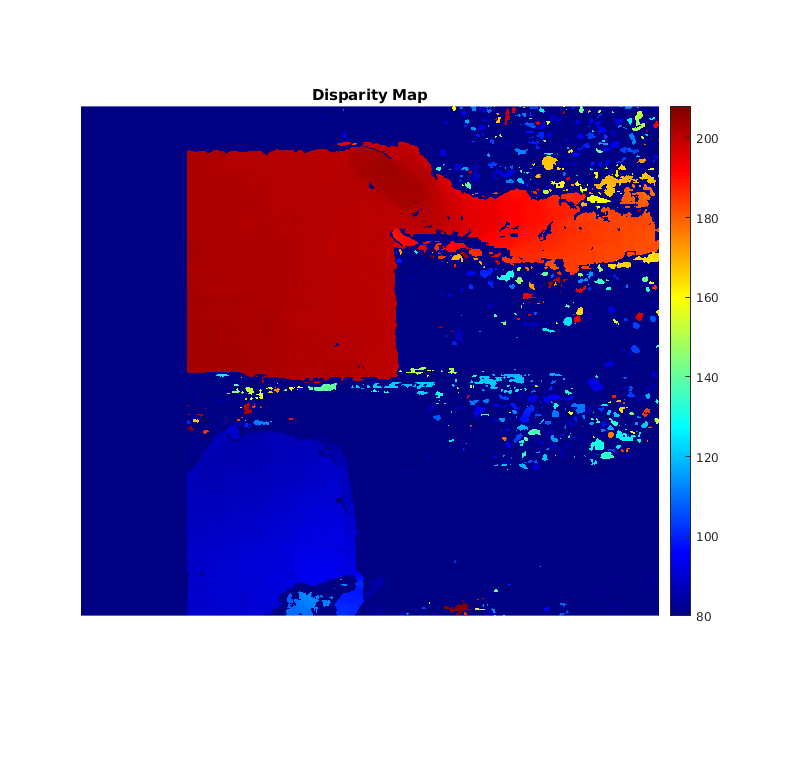

disparityRange = [16*5 256-16*3];
disparityMap = disparity(J1, J2, "disparityRange", disparityRange, "BlockSize", 15, "UniquenessThreshold", 25, "ContrastThreshold", 0.5);
figure
imshow(disparityMap, disparityRange)
title('Disparity Map')
colormap jet
colorbar

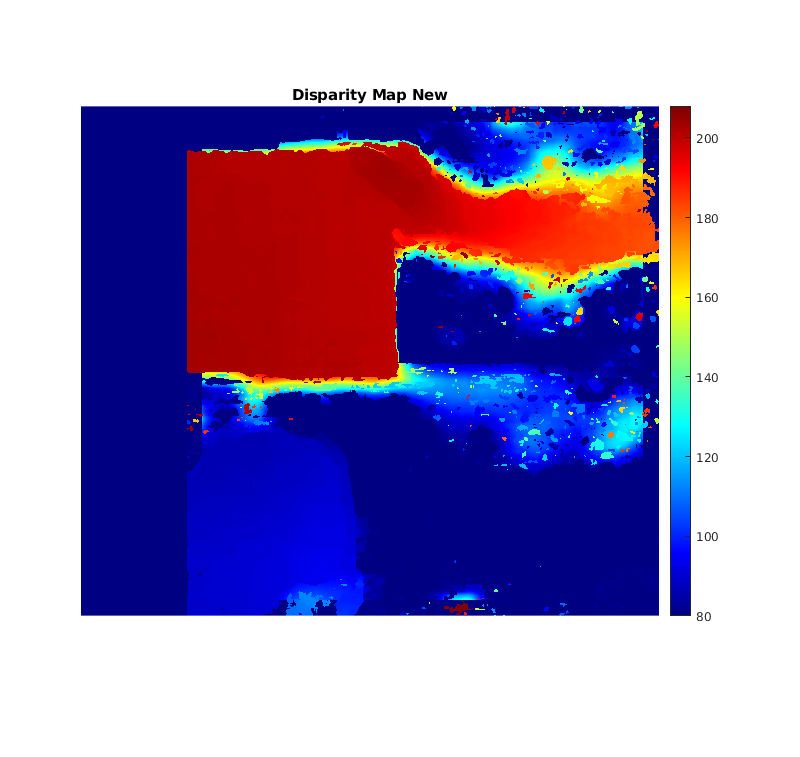

win = 30;
for i=disparityRange(2)+win+1:size(disparityMap, 2)-win-1
    for j=win+1:size(disparityMap, 1)-win-1
        if disparityMap(j, i) < 0
            tmp = disparityMap(j-win:j+win, i-win:i+win);
            disparityMap(j, i) = mean(tmp(tmp>0));
        end
    end
end
figure
imshow(disparityMap, disparityRange)
title('Disparity Map New')
colormap jet
colorbar

Rekonstrukcja sceny i wyświetlenie gęstej chmury punktów

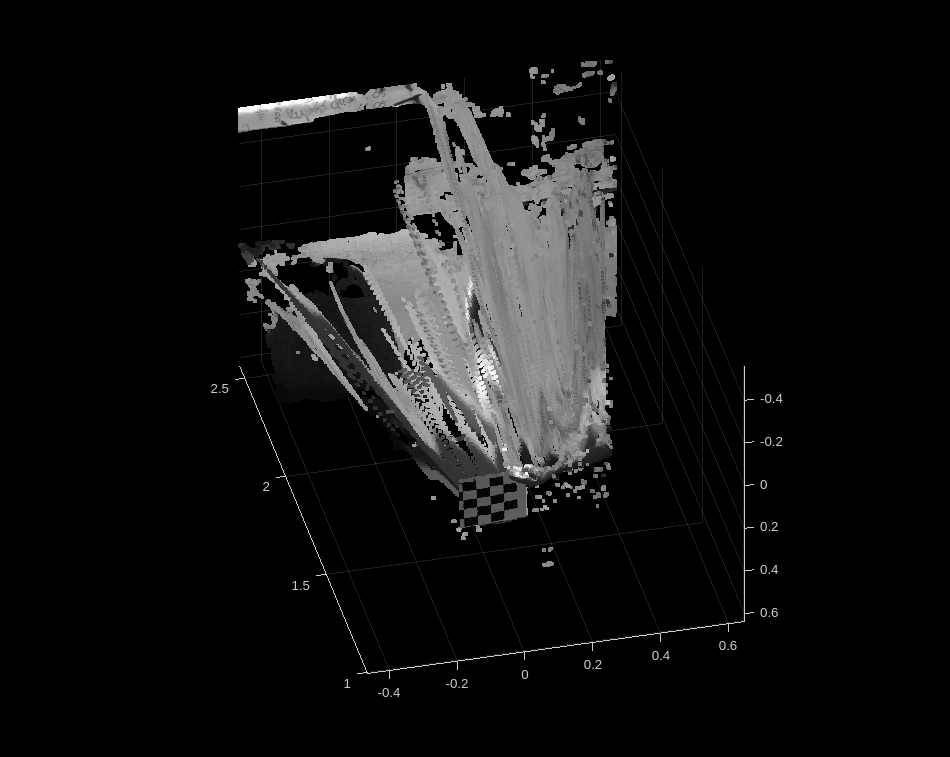

points3D = reconstructScene(disparityMap, stereoParams);

J1_col = cat(3, J1, J1, J1);

points3D = points3D ./ 1000;
ptCloud = pointCloud(points3D, 'Color', J1_col);

pcshow(ptCloud, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', 'MarkerSize', 45);

## Progowanie głębi i rozmycie tła

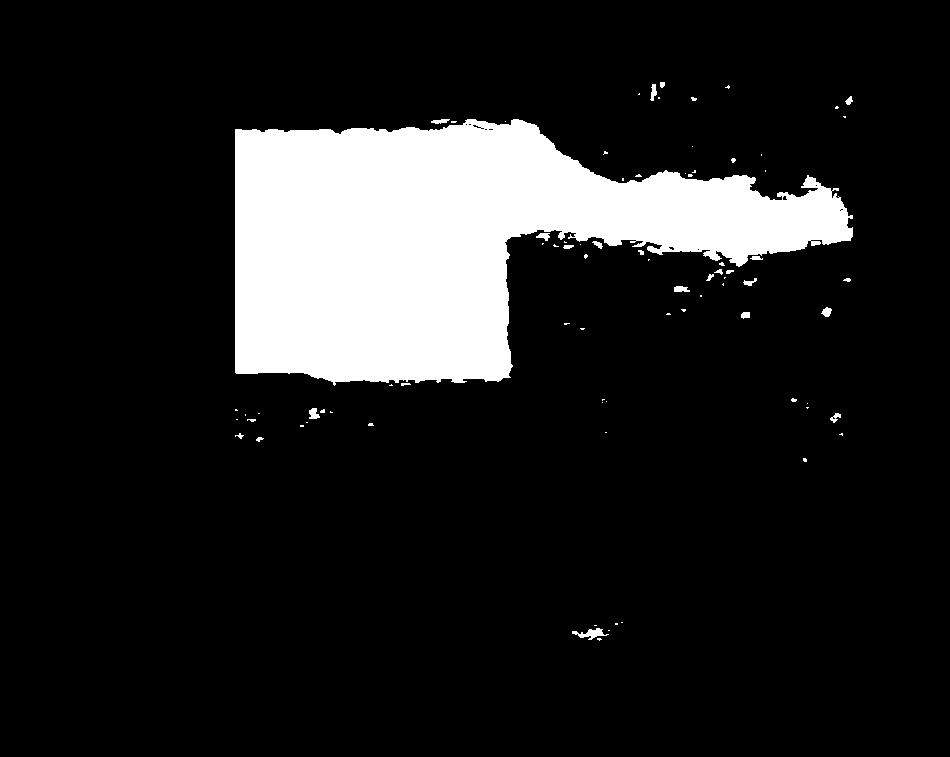

mask = disparityMap > 180;
imshow(mask);

Obraz wejściowy poddajmy rozmyciu, np. Gaussa, z dość dużym oknem:

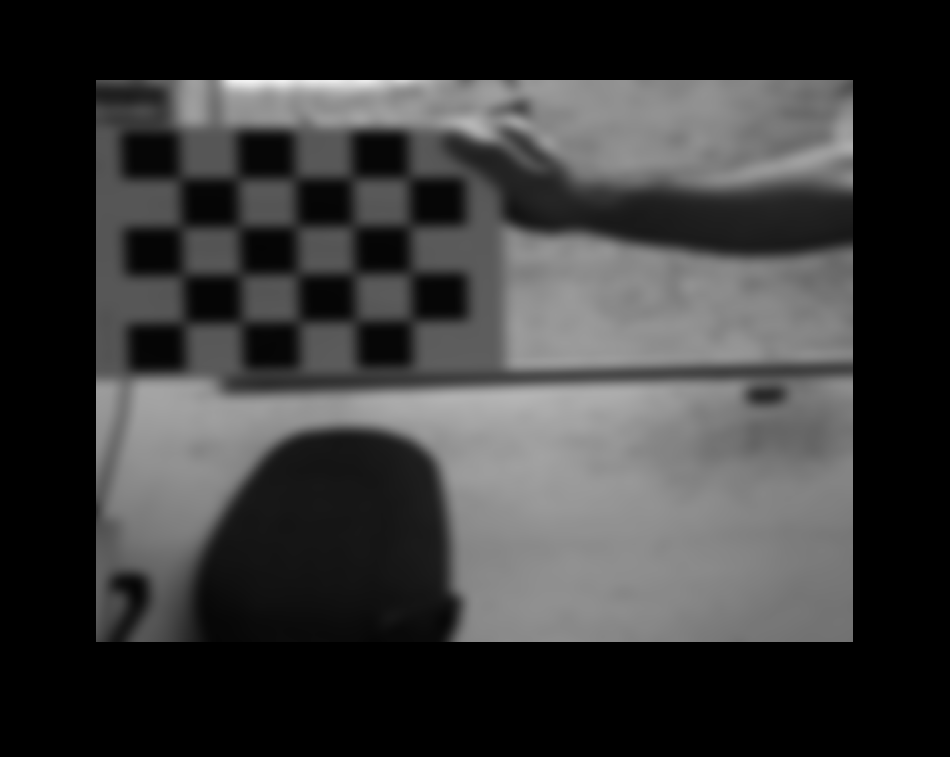

blur = imgaussfilt(J1, 10);
imshow(blur);

Ostatecznie możemy dokonać zmieszania obu obrazów z wykorzystaniem wygenerowanej maski:

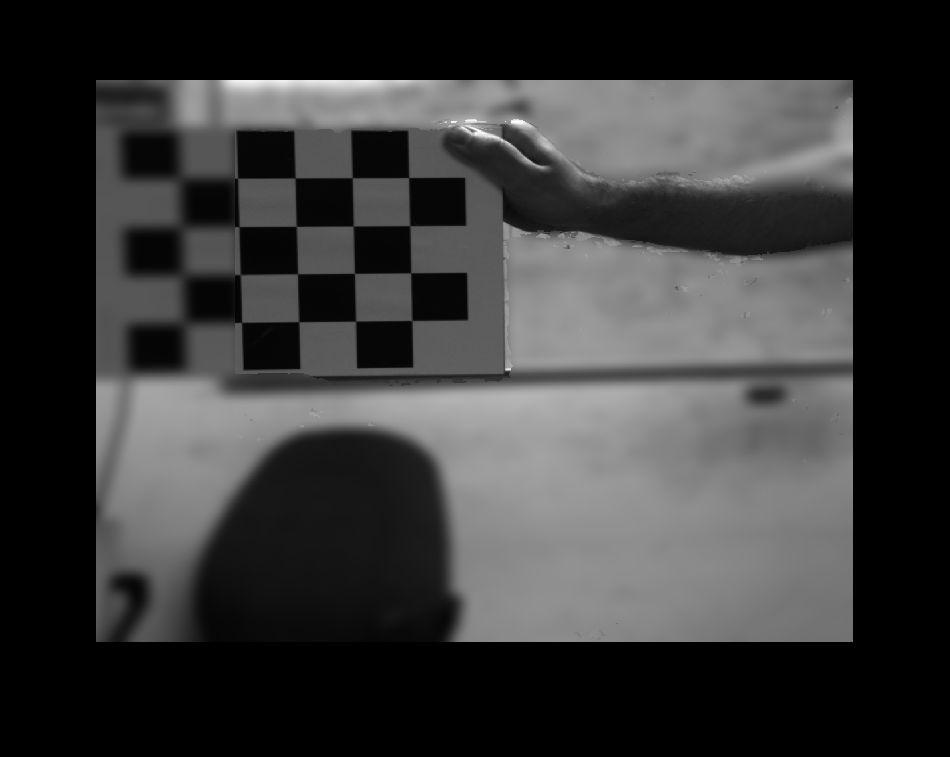

blur(mask ~= 0) = J1(mask ~= 0);
imshow(blur);